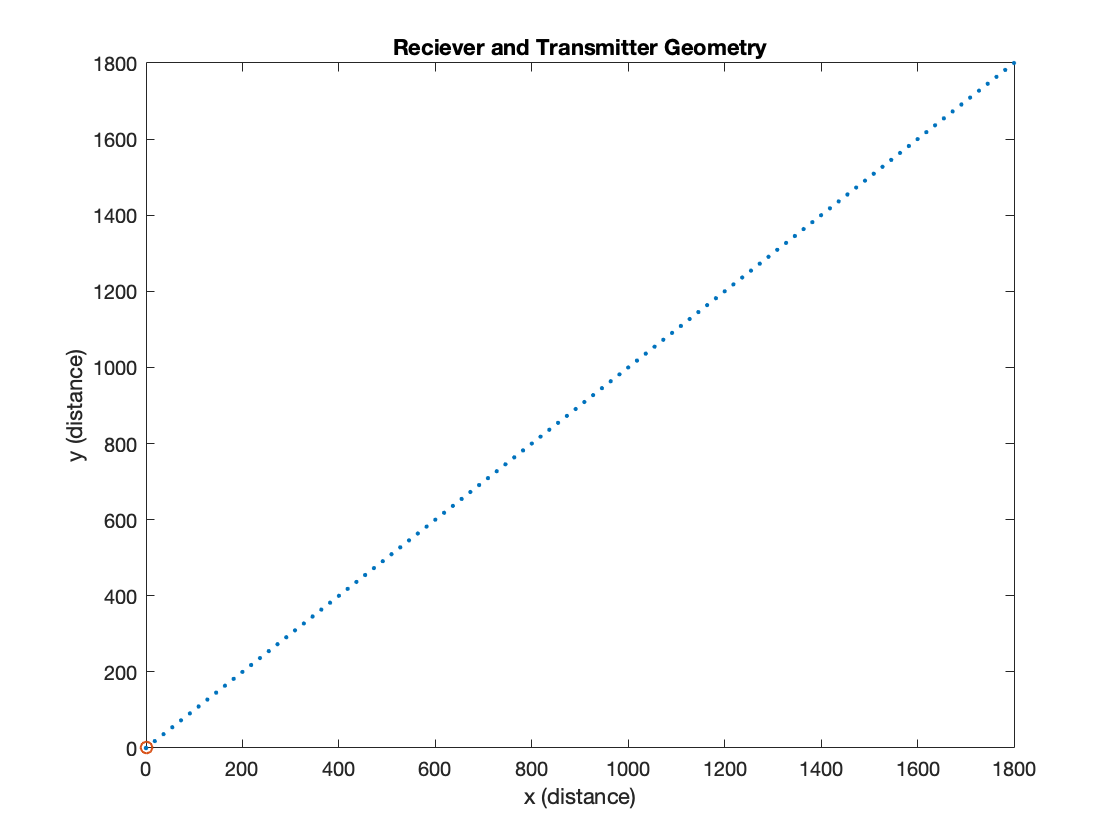

% As with all good things in engineering... best intentions to take an
% object-oriented approach to keep things neat&tidy... 
% But naturally copy and paste wins out in the end
clear all; close all; 
%% Initial setup
%%%%%%%%% Cartesian Coordinates %%%%%%%%%
%  = [x0, y0; Position t(1) // refl(1)  % 
%     x1, y1; Position t(2) // refl(2)  %
%      .   .                            %
%      .   .                            %
%      .   .                            %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Tx.pos = [0, 0]; % Transmitter fixed at origin
% Parameters that will not change
global C;       C       = 3E8;     
global fc;      fc      = 900E6; 
global lambdaC; lambdaC = C/fc; 
global Grx;     Grx     = 1; 
global Gtx;     Gtx     = 1; 
global W;       W       = 1E7;
                       % I hate globals, but this is so much easier...
                       
load('mp1data.mat');   % Reflector Positions
reflectors{1}.pos = dreflect1; 
reflectors{2}.pos = dreflect2; 

%% (a): Geometric set-up
% Assume a given initial reciever position and speed
Rx.posInit = [0, 0]; % Start colocated and and then spread
Rx.V       = [1, 1]; % at 1 m/s in both directions
timeArray  = linspace(0, 3600/2); % Take a half-hour of data
% Not exactly a function of time, but... kind-of
    Rx.pos     = recieverPosition(Rx.posInit, Rx.V, timeArray); 
    t_ind = length(Rx.pos); % let's look torwards end of data
    reflectors{1}.range  = pathLength(Tx.pos, Rx.pos(t_ind,:), reflectors{1}.pos); % Be sure to add DP
    reflectors{2}.range  = pathLength(Tx.pos, Rx.pos(t_ind,:), reflectors{2}.pos);
    plot(Rx.pos(:,1), Rx.pos(:,2), '.'); hold on; plot(Tx.pos(1), Tx.pos(2), 'o'); 
    title('Reciever and Transmitter Geometry'); xlabel(['x (distance)']); ylabel('y (distance)')

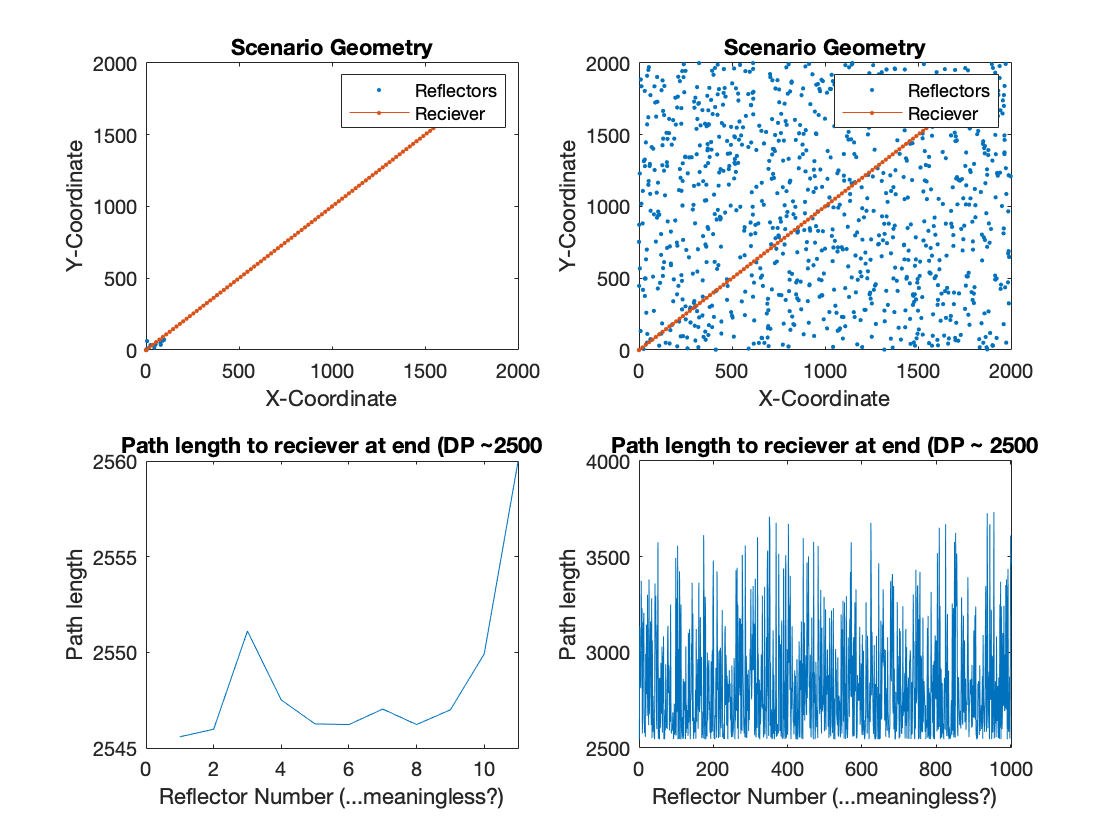

    subplot(2,2,1);  title('Reflector Set 1'); 
    plot(reflectors{1}.pos(:,1), reflectors{1}.pos(:,2), '.'); hold on; 
    plot(Rx.pos(:,1), Rx.pos(:,2), '.-'); 
    xlabel('X-Coordinate'); ylabel('Y-Coordinate'); 
    title('Scenario Geometry'); legend('Reflectors','Reciever')

    subplot(2,2,2); title('Reflector Set 2'); 
    plot(reflectors{2}.pos(:,1), reflectors{2}.pos(:,2), '.'); hold on; 
    plot(Rx.pos(:,1), Rx.pos(:,2), '.-'); 
    xlabel('X-Coordinate'); ylabel('Y-Coordinate'); 
    title('Scenario Geometry'); legend('Reflectors', 'Reciever')

    subplot(2,2,3); plot(reflectors{1}.range); title('Path length to reciever at end (DP ~2500'); 
    xlabel('Reflector Number (...meaningless?)'); ylabel('Path length'); 

    subplot(2,2,4); plot(reflectors{2}.range); title('Path length to reciever at end (DP ~ 2500') 
    xlabel('Reflector Number (...meaningless?)'); ylabel('Path length'); 

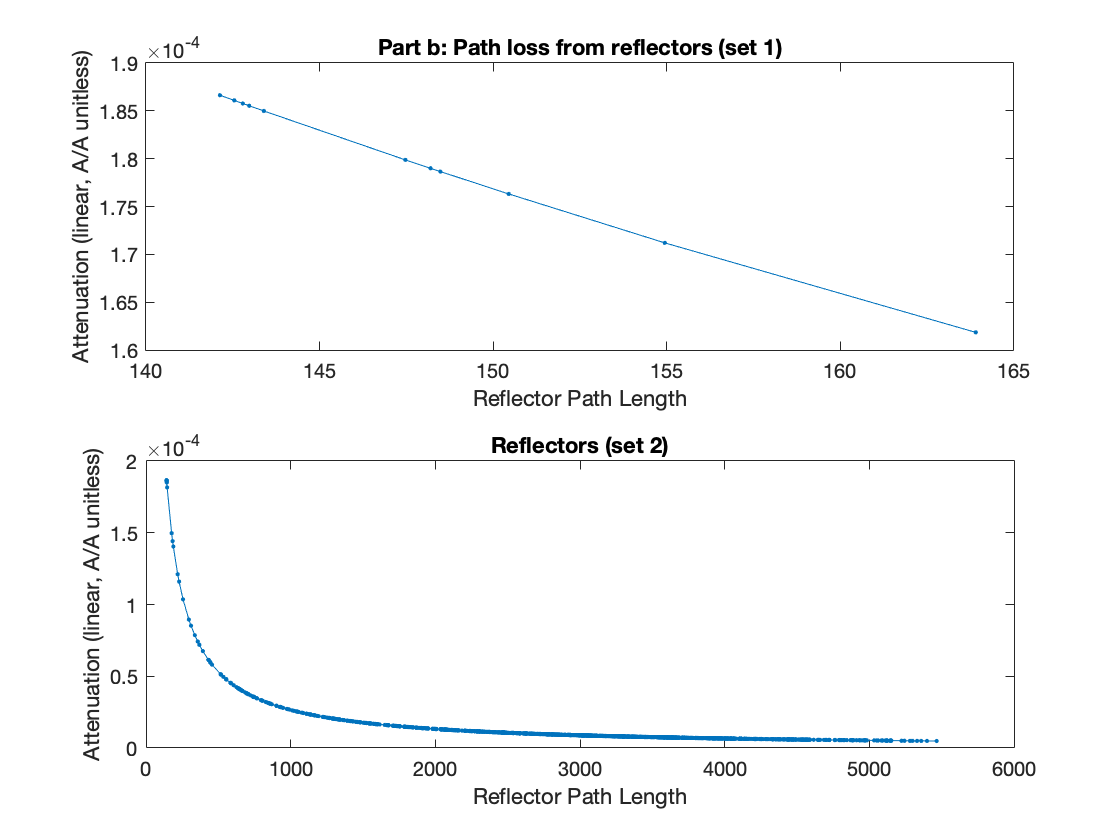

% Looks as expected...
    
%% (b): calculate, at a given time t, the attenuation a_i(t) and delay T_i(t) for each path
% Requires pathlength (range)
clear Rx.pos timeArray; 
Rx.posInit = [100, 100]; % Arbitray;
Rx.V       = [1, 1]; 
timeArray   =  1; % Let's take one time value; 
% May throw this into a function for clarity as a function of time; 
    Rx.pos     = recieverPosition(Rx.posInit, Rx.V, timeArray); 
    reflectors{1}.range  = pathLength(Tx.pos, Rx.pos, reflectors{1}.pos);
    reflectors{1}.rangeS = sort(pathLength(Tx.pos, Rx.pos, reflectors{1}.pos));
    reflectors{2}.range  = pathLength(Tx.pos, Rx.pos, reflectors{2}.pos); 
    reflectors{2}.rangeS = sort(reflectors{2}.range); % For neater plotting for large N reflectors

reflectors{1}.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors{1}.range);
reflectors{1}.attenS = pathAttenuation(Grx, Gtx, lambdaC, reflectors{1}.rangeS);
reflectors{2}.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors{2}.range);
reflectors{2}.attenS = pathAttenuation(Grx, Gtx, lambdaC, reflectors{2}.rangeS);
figure; subplot(2,1,1); plot(reflectors{1}.rangeS, reflectors{1}.attenS, '.-'); 
xlabel('Reflector Path Length'); ylabel('Attenuation (linear, A/A unitless)'); 
title('Part b: Path loss from reflectors (set 1)'); 
subplot(2,1,2);  plot(reflectors{2}.rangeS, reflectors{2}.attenS, '.-');
xlabel('Reflector Path Length'); ylabel('Attenuation (linear, A/A unitless)'); 
title('Reflectors (set 2)'); 

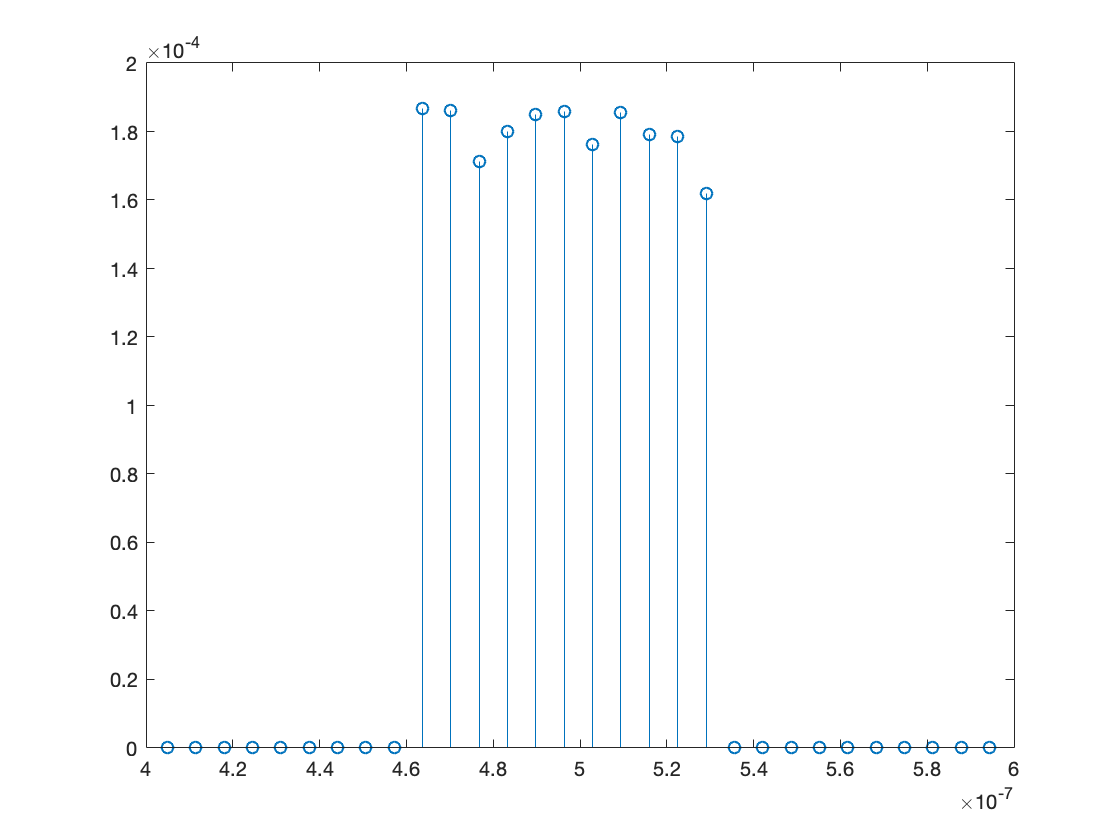


%% (c): Continuous time channel IR and frequency response
% Plot power spectrum in decibels at a given time
% I do not understand this part and my results are garbage... moving on

% I am really not sure how to define these variables as a function of time
% I think I need to get more analytical

reflectors{1}.pDelay = pathDelay(reflectors{1}, C); 
reflectors{2}.pDelay = pathDelay(reflectors{2}, C);
% It seems silly to plot anything besides 
[reflectors{1}.h, channelImpt] = channelImpResp(reflectors{1}, reflectors{1}.pDelay, length(reflectors{2}.pDelay)+100); 
figure; stem(channelImpt, reflectors{1}.h); xlim([0.4 0.6].*1E-6); 

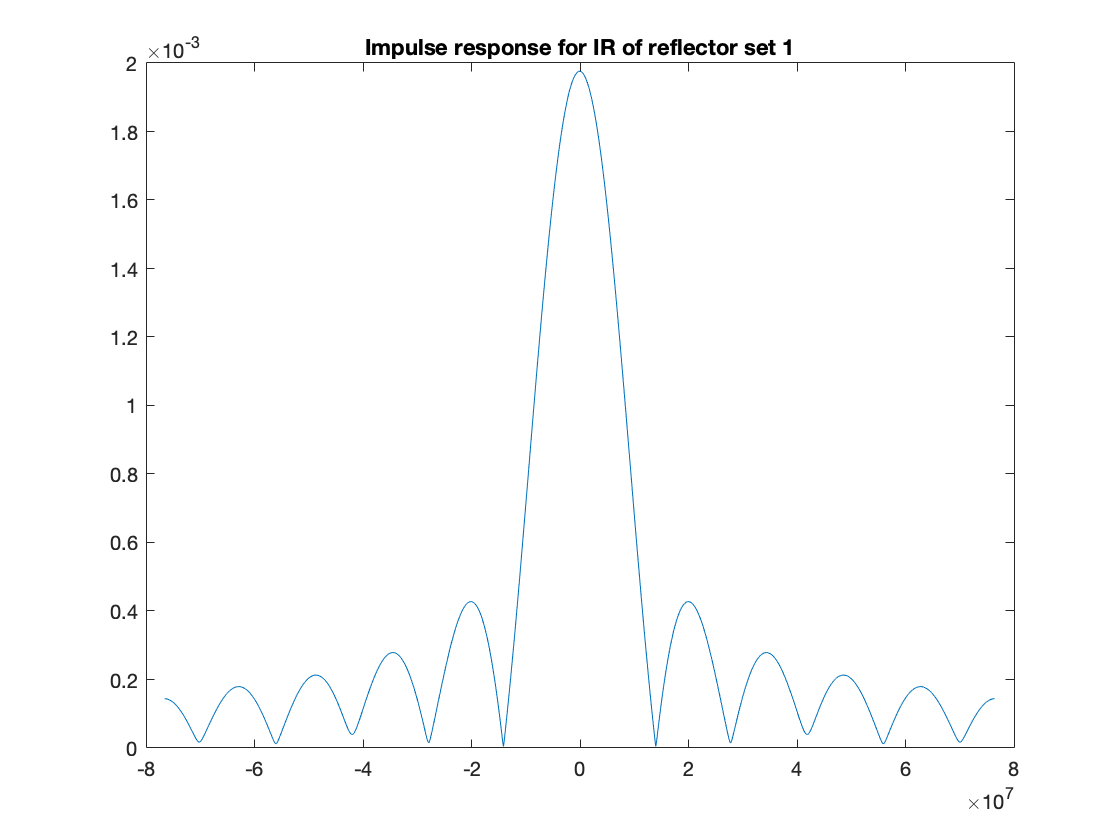

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors{1}.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('Impulse response for IR of reflector set 1'); 

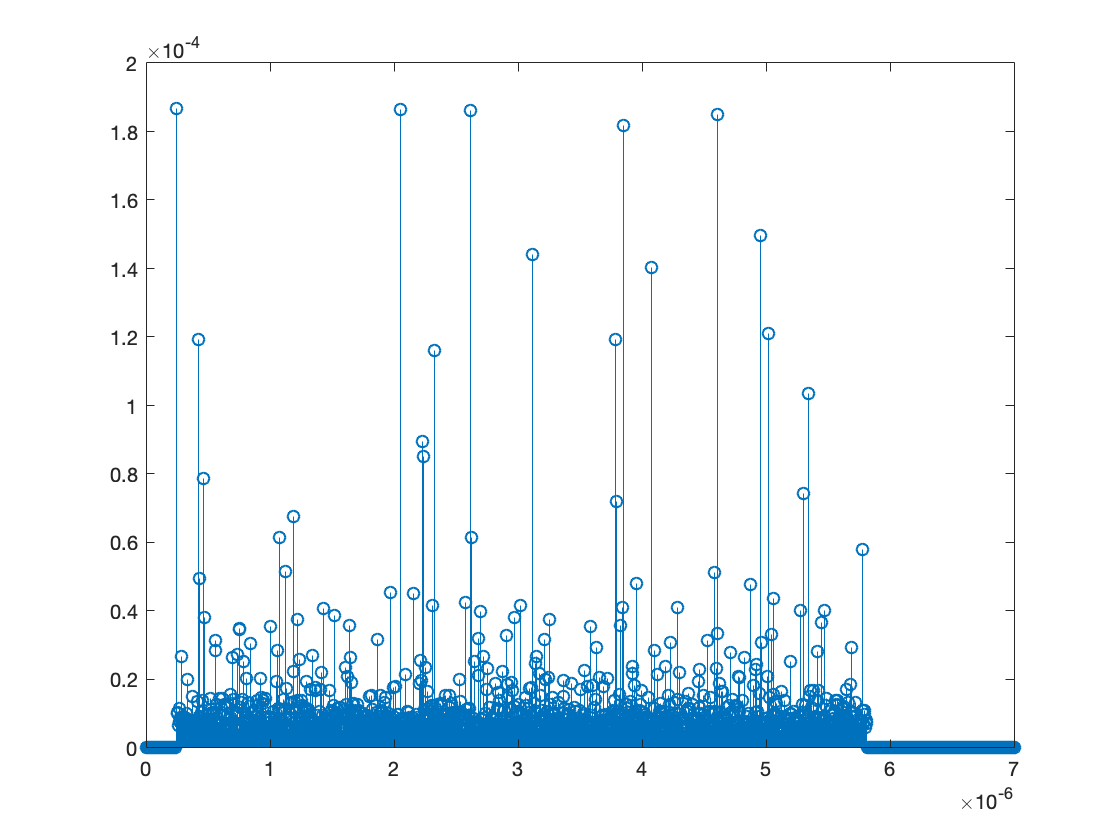


[reflectors{2}.h, channelImpt] = channelImpResp(reflectors{2}, reflectors{2}.pDelay, length(reflectors{2}.pDelay)+100); 
figure; stem(channelImpt, reflectors{2}.h); xlim([0, 0.7E-5]);

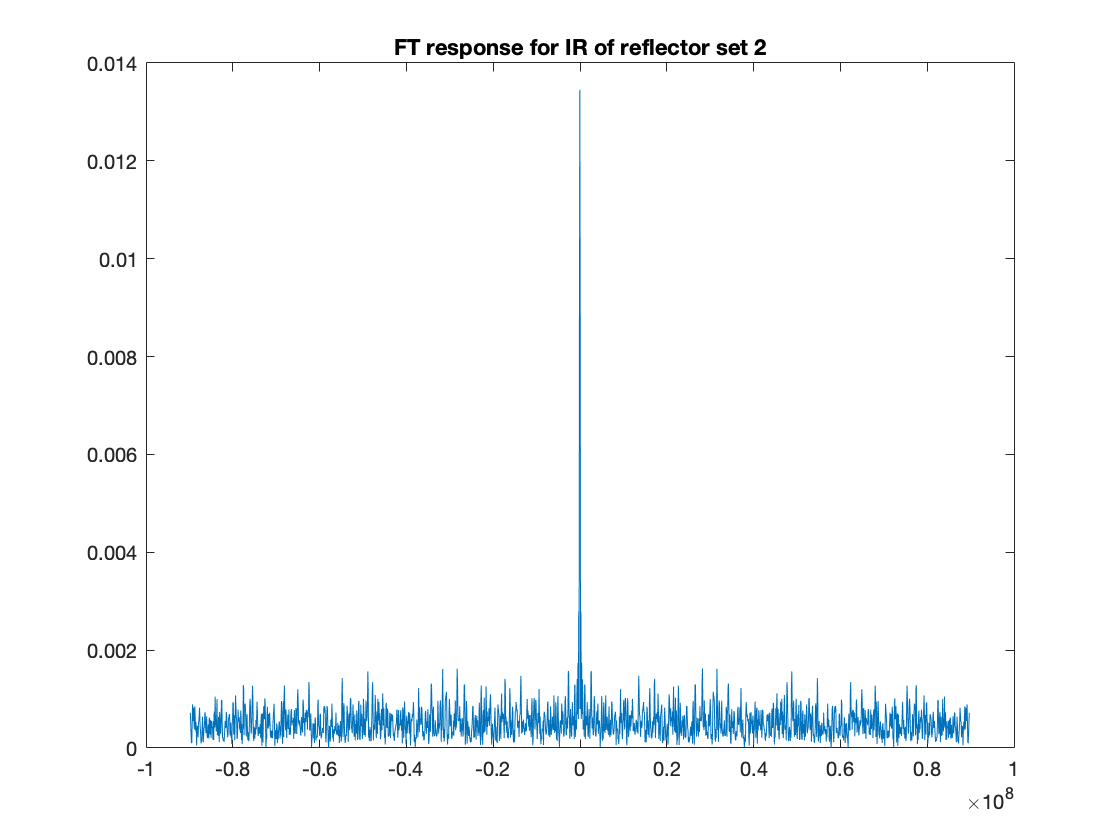

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors{2}.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('FT response for IR of reflector set 2'); 

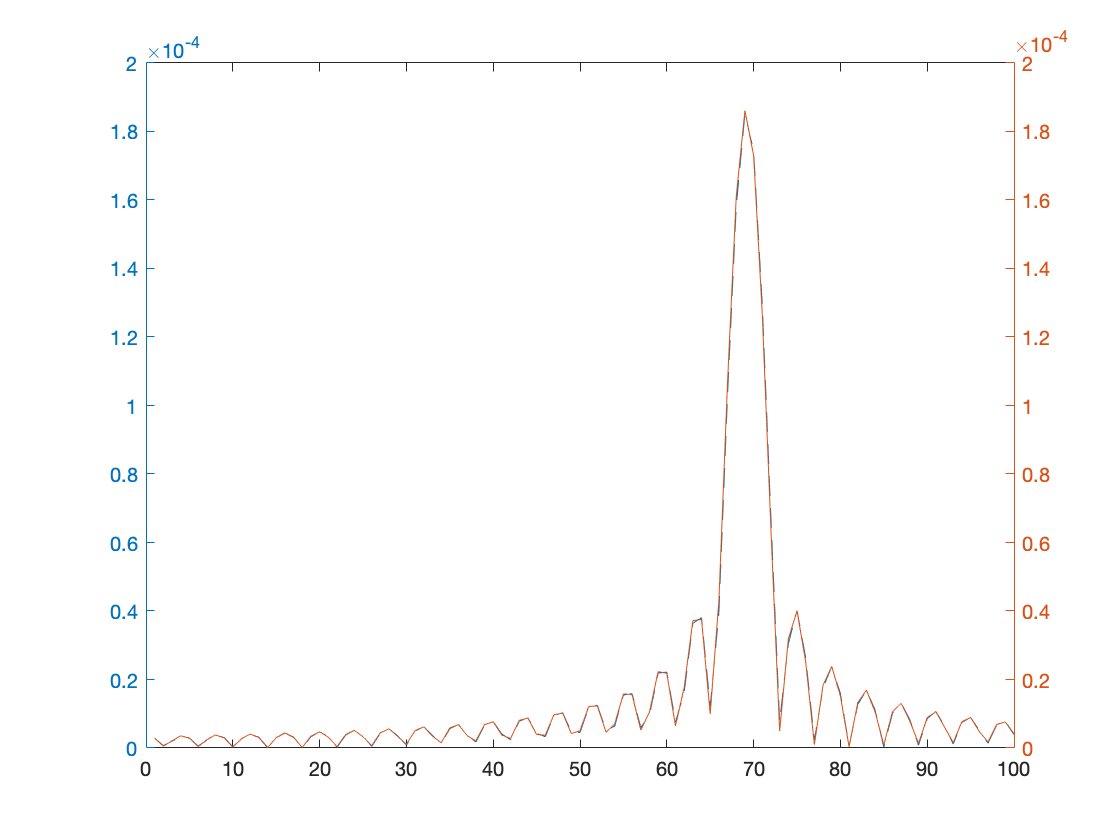

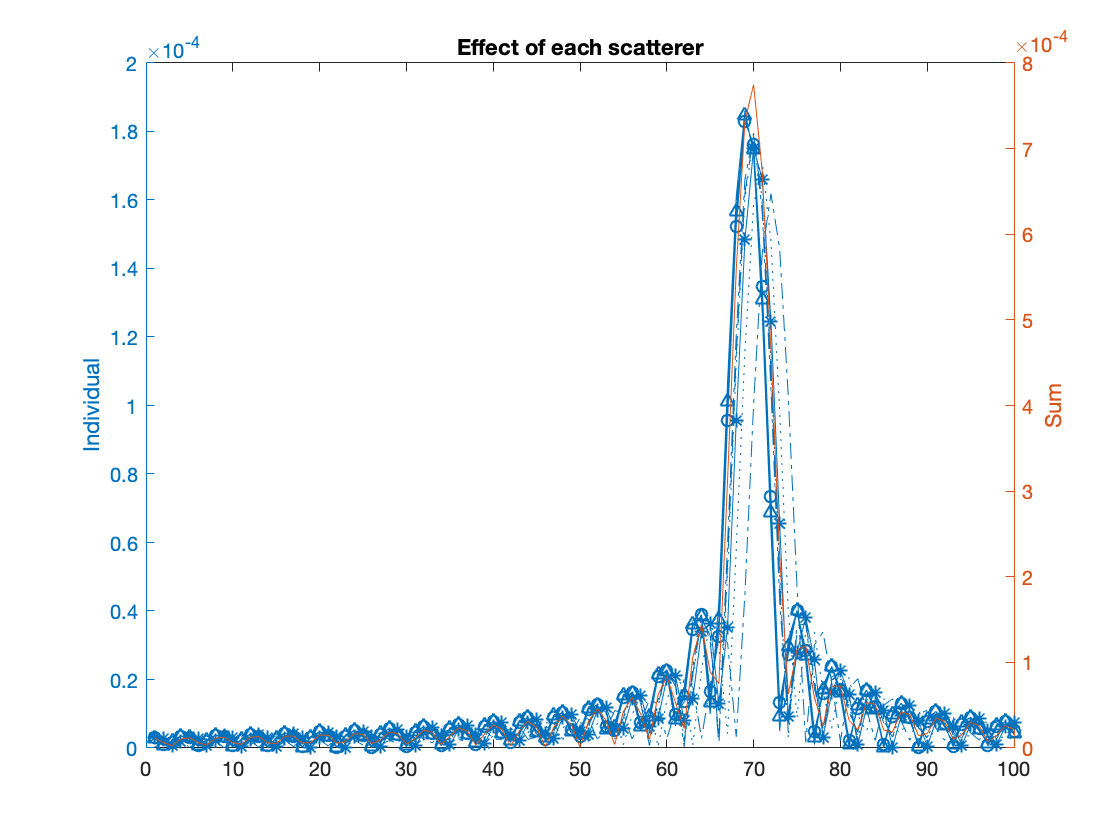




%% (d): Discrete time baseband equivalent model
% h = @(m, w, rx) (sum( rx.
figure; 
h = dtbIR(reflectors{1}); 

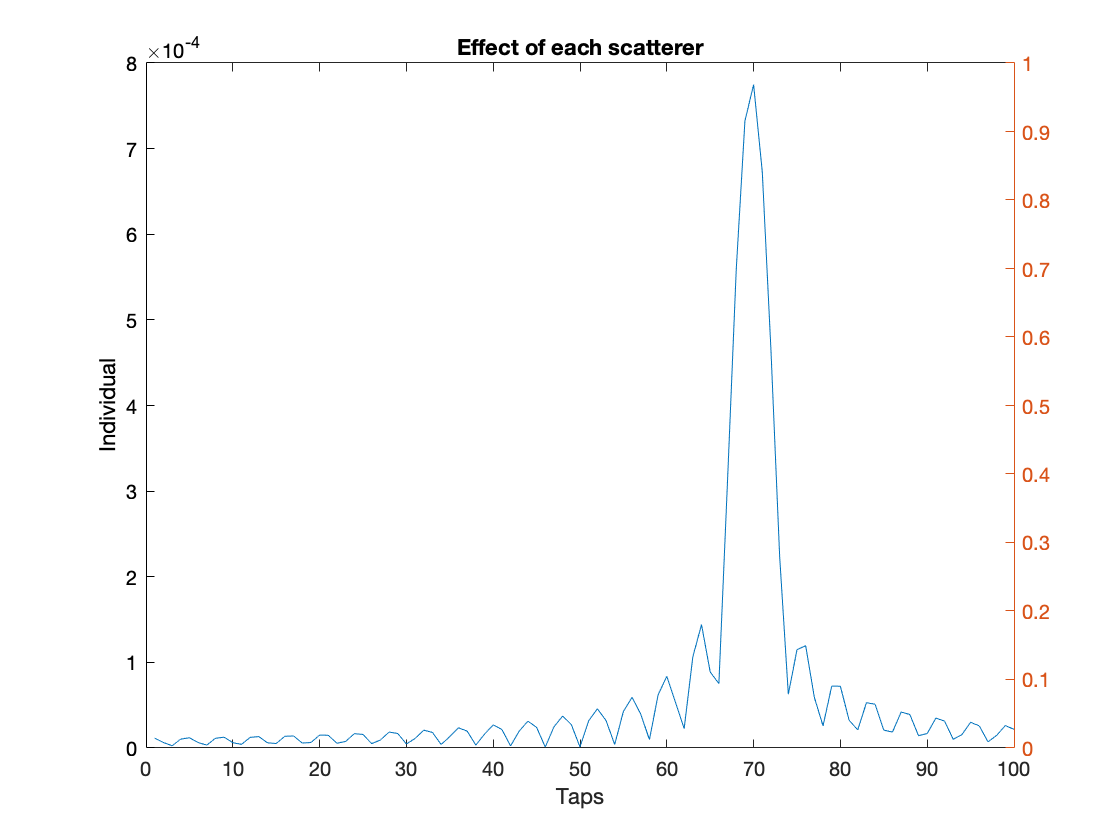

plot(abs(h(1,:))); clear h;
xlabel('Taps'); ylabel('Amplitude?'); 
h = dtbIR(reflectors{2}); 

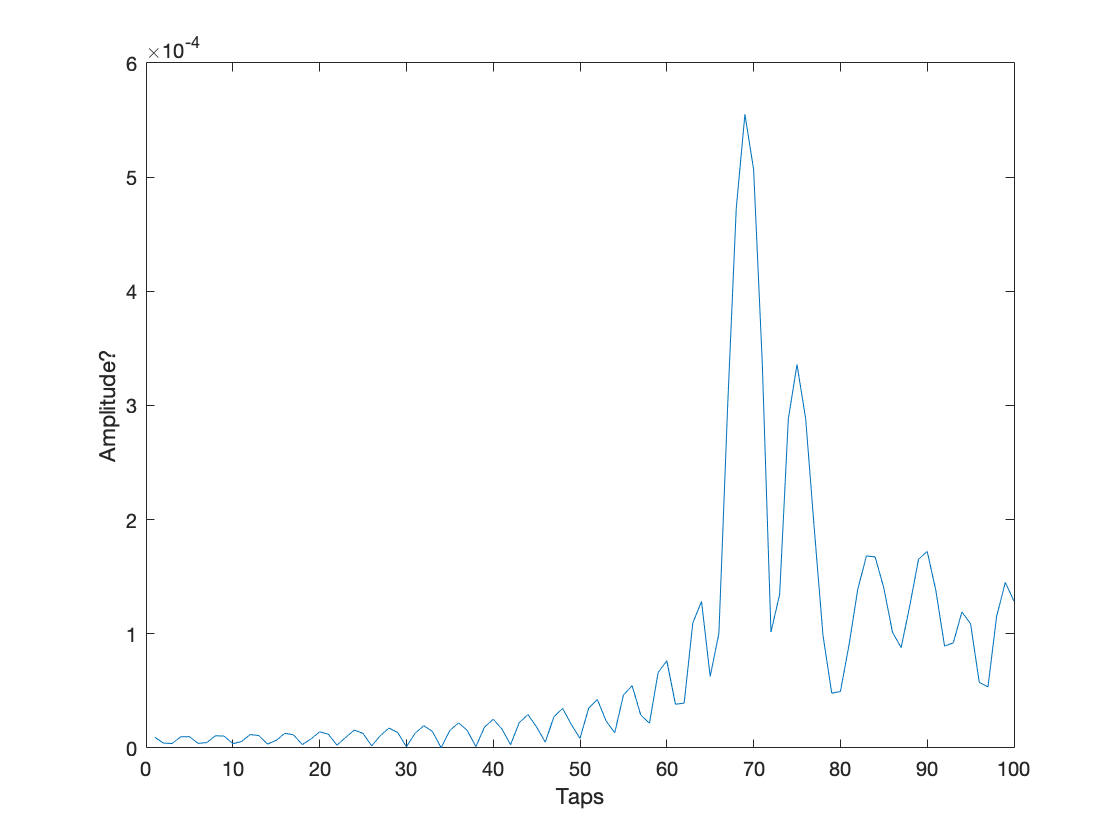

plot(abs(h(1,:))); xlabel('Taps'); ylabel('Amplitude?'); 

%% (e): Delay spread
reflectors{1} = delaySpread(reflectors{1}, W, C, fc); 


The delay spread is 0.073 us
The coherance bandwidth is 6890.647 kHz
The signal is in a flat fading zone


reflectors{2} = delaySpread(reflectors{2}, W, C, fc); 


The delay spread is 17.744 us
The coherance bandwidth is 28.178 kHz
The signal is in a Frequency selective fading zone



%% (f): Doppler spread
% This is more tricky. Have to account for v and directions
% Wouldn't this actually be a bistatic doppler calculation??
global C; C = 3E8; 
Rx.V       = [1, 1];     Rx.posInit = [0 0]; 
Rx.pos     = recieverPosition(Rx.posInit, Rx.V, 0:10);
reflectors{1} = dopplerSpread(reflectors{1}, Rx, W, fc, C); 


The doppler spread is 1.00798 Hz
The coherance time is 248.02115 ms

The doppler spread is 1.00798 Hz
The coherance time is 248.02115 ms

The doppler spread is 2.94180 Hz
The coherance time is 84.98211 ms

The doppler spread is 6.15718 Hz
The coherance time is 40.60302 ms

The doppler spread is 7.60430 Hz
The coherance time is 32.87612 ms

The doppler spread is 8.04746 Hz
The coherance time is 31.06571 ms

The doppler spread is 8.21516 Hz
The coherance time is 30.43156 ms

The doppler spread is 8.29294 Hz
The coherance time is 30.14613 ms

The doppler spread is 8.33425 Hz
The coherance time is 29.99671 ms

The doppler spread is 8.35829 Hz
The coherance time is 29.91043 ms

The doppler spread is 8.37316 Hz
The coherance time is 29.85731 ms

The doppler spread is 8.38271 Hz
The coherance time is 29.82328 ms


reflectors{2} = dopplerSpread(reflectors{2}, Rx, W, fc, C); 


The doppler spread is 1.24143 Hz
The coherance time is 201.38084 ms

The doppler spread is 1.24143 Hz
The coherance time is 201.38084 ms

The doppler spread is 1.24541 Hz
The coherance time is 200.73654 ms

The doppler spread is 1.24949 Hz
The coherance time is 200.08196 ms

The doppler spread is 1.25629 Hz
The coherance time is 198.99888 ms

The doppler spread is 1.26313 Hz
The coherance time is 197.92027 ms

The doppler spread is 1.27003 Hz
The coherance time is 196.84612 ms

The doppler spread is 1.27697 Hz
The coherance time is 195.77643 ms

The doppler spread is 1.28395 Hz
The coherance time is 194.71120 ms

The doppler spread is 1.39976 Hz
The coherance time is 178.60262 ms

The doppler spread is 1.61501 Hz
The coherance time is 154.79805 ms

The doppler spread is 1.86905 Hz
The coherance time is 133.75764 ms


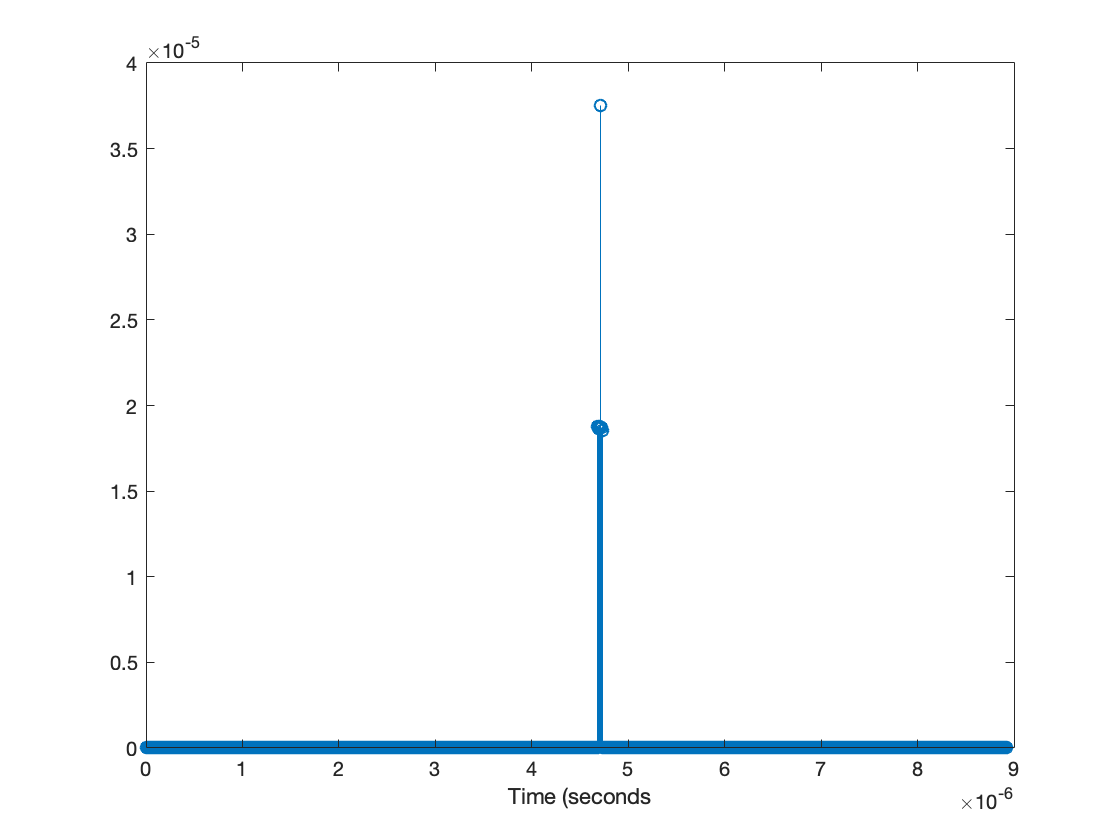


%% (g): ...Load data. Already done
%% (h & i): Parametric evaluation
fc = 900E6; 
W  = 1E6; 
% Take one: r1
clear Rx; clear reflectors; 
reflectors.pos = dreflect1; 
Rx.V       = [1,1]; Rx.posInit = [1000, 900]; 
Rx.pos     = recieverPosition(Rx.posInit, Rx.V, 0); 
reflectors.range  = pathLength(Tx.pos, Rx.pos, reflectors.pos);
reflectors.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors.range);
reflectors.pDelay = pathDelay(reflectors, C);
[reflectors.h, channelImpt] = channelImpResp(reflectors, reflectors.pDelay, length(reflectors.pDelay)+2000); 
figure; stem(channelImpt, reflectors.h); xlabel('Time (seconds'); 

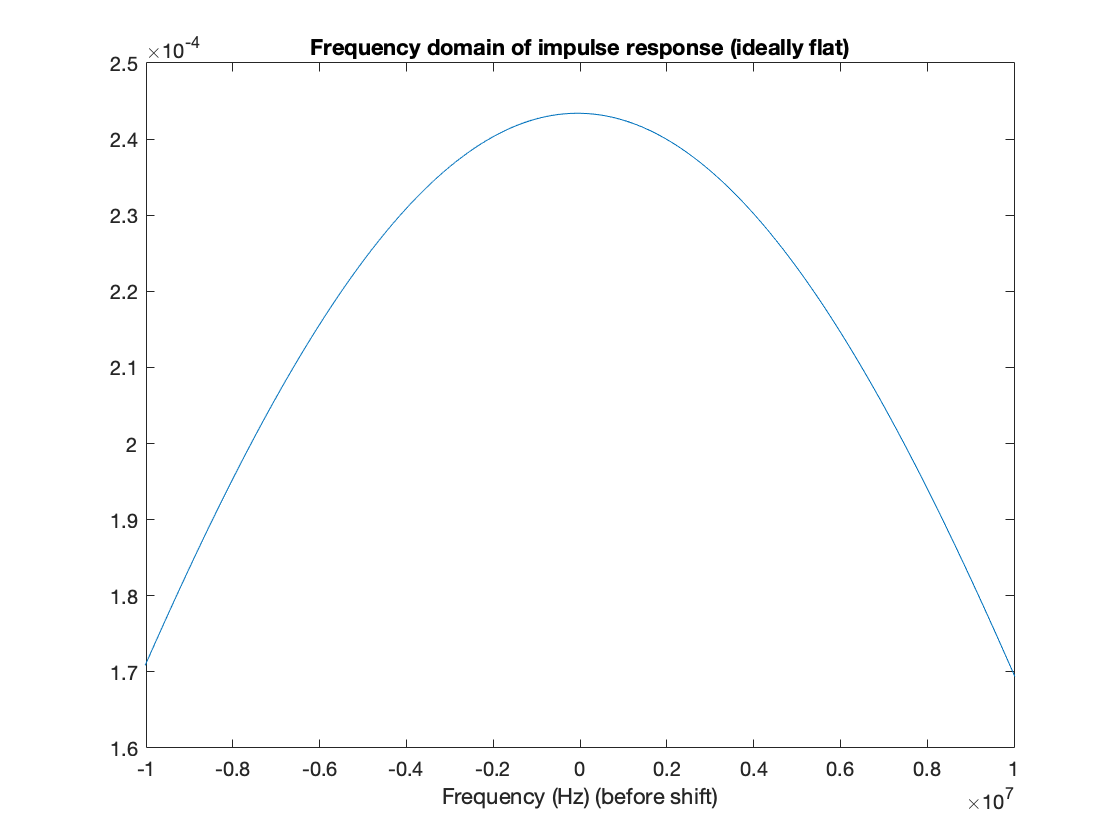

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('Fourier transform before shift')
xlim([-10E6, 10E6]); xlabel('Frequency (Hz) (before shift)'); 
title('Frequency domain of impulse response (ideally flat)'); 

delaySpread(reflectors, W, C, fc); dopplerSpread(reflectors, Rx, W, fc, C); 


The delay spread is 0.049 us
The coherance bandwidth is 10245.903 kHz
The signal is in a flat fading zone

The doppler spread is 0.01308 Hz
The coherance time is 19116.14629 ms

The doppler spread is 0.01308 Hz
The coherance time is 19116.14629 ms


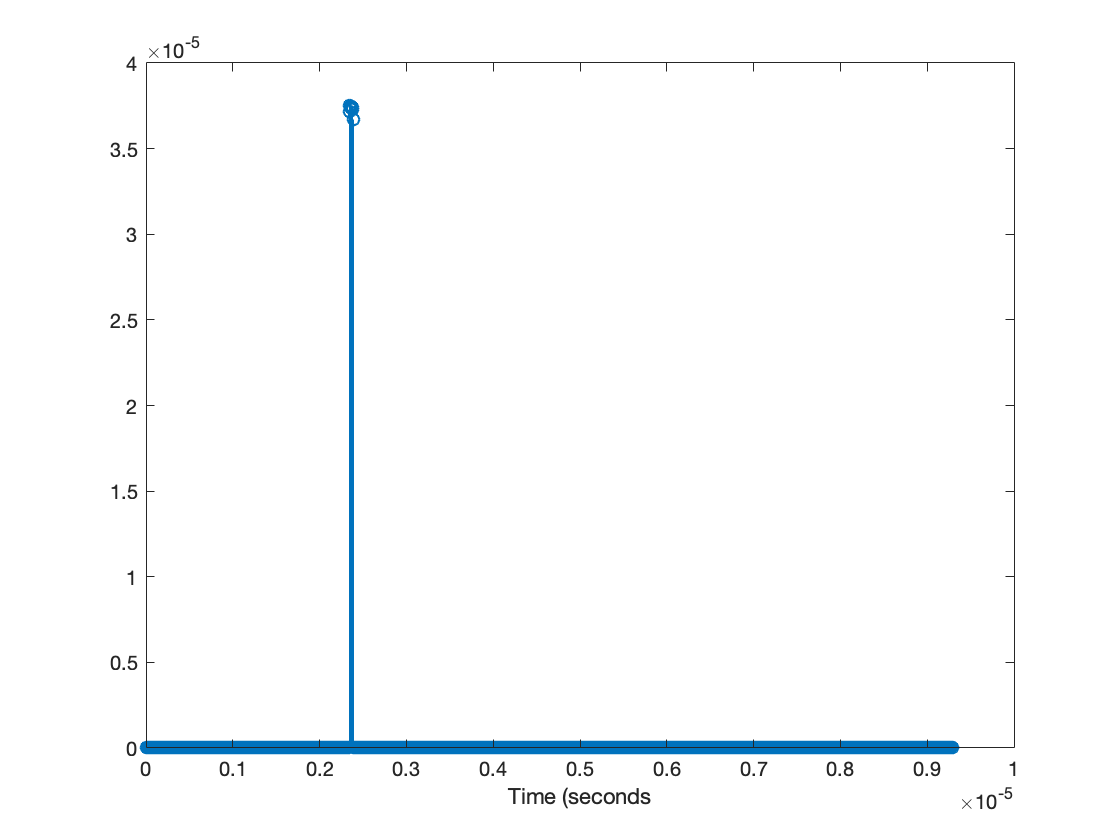

% Take two: r1
clear Rx reflector
Rx.V       = [10,10]; 
Rx.posInit = [500, 1200]; 
reflectors.pos = dreflect1; 
Rx.pos     = recieverPosition(Rx.posInit, Rx.V, 0); 
reflectors.range  = pathLength(Tx.pos, Rx.pos, reflectors.pos);
reflectors.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors.range);
reflectors.pDelay = pathDelay(reflectors, C);
[reflectors.h, channelImpt] = channelImpResp(reflectors, reflectors.pDelay, length(reflectors.pDelay)+2000); 
figure; stem(channelImpt, reflectors.h); xlabel('Time (seconds'); 

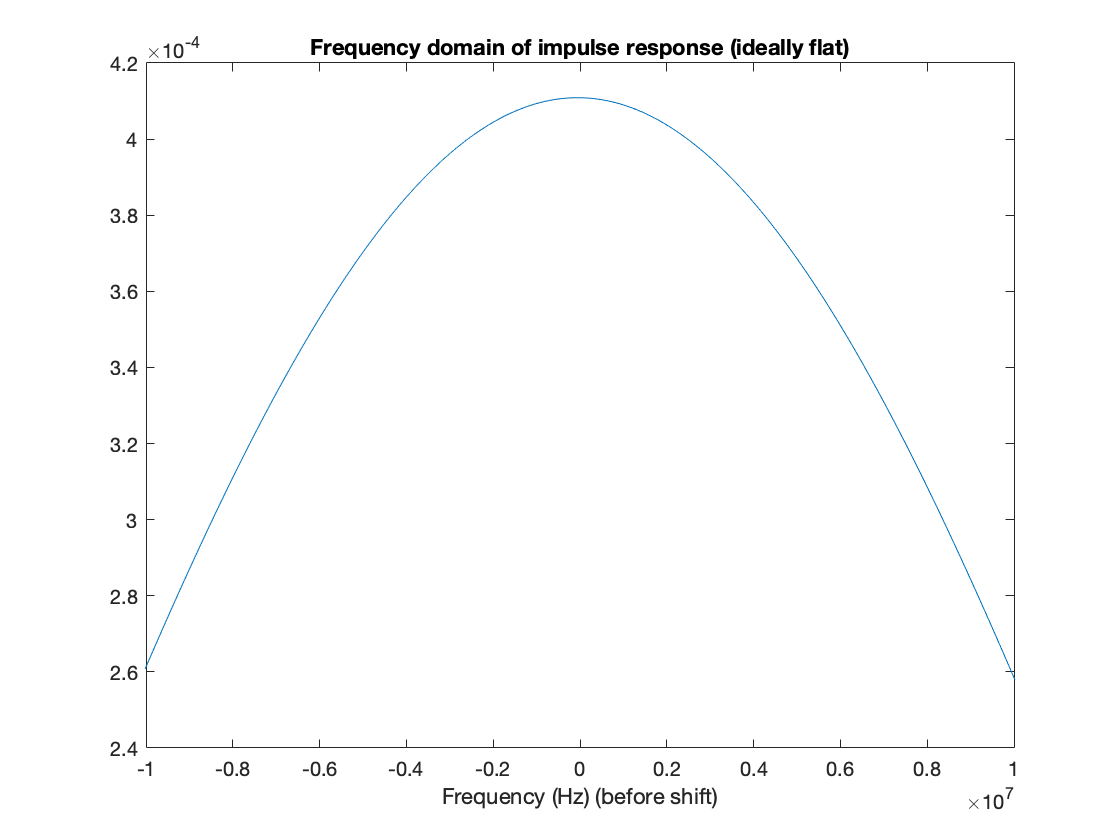

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('Fourier transform before shift')
xlim([-10E6, 10E6]); xlabel('Frequency (Hz) (before shift)'); 
title('Frequency domain of impulse response (ideally flat)'); 

delaySpread(reflectors, W, C, fc); 


The delay spread is 0.051 us
The coherance bandwidth is 9835.041 kHz
The signal is in a flat fading zone


dopplerSpread(reflectors, Rx, W, fc, C); 


The doppler spread is 1.12698 Hz
The coherance time is 221.83150 ms

The doppler spread is 1.12698 Hz
The coherance time is 221.83150 ms


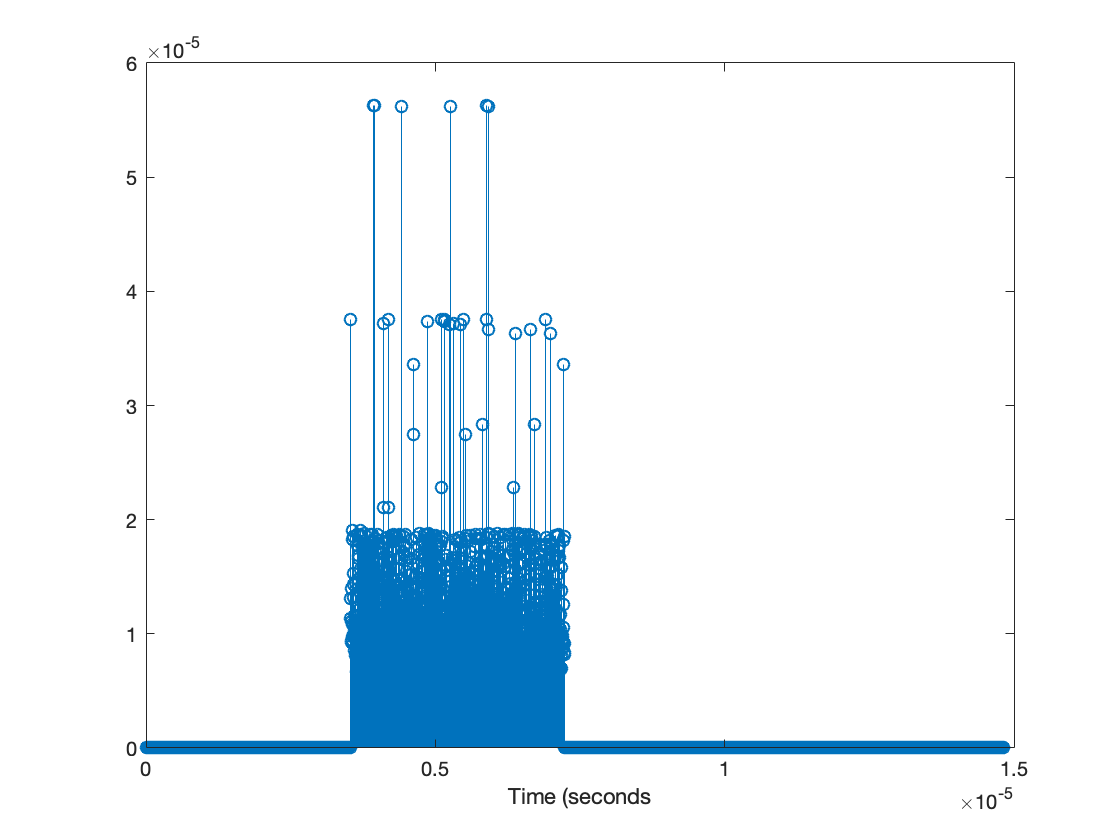


% Take three: r2
clear Rx reflector
Rx.V       = [1,1]; 
Rx.posInit = [1000, 900]; 
reflectors.pos = dreflect2; 
Rx.pos     = recieverPosition(Rx.posInit, Rx.V, 0); 
reflectors.range  = pathLength(Tx.pos, Rx.pos, reflectors.pos);
reflectors.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors.range);
reflectors.pDelay = pathDelay(reflectors, C);
[reflectors.h, channelImpt] = channelImpResp(reflectors, reflectors.pDelay, length(reflectors.pDelay)+2000); 
figure; stem(channelImpt, reflectors.h); xlabel('Time (seconds'); 

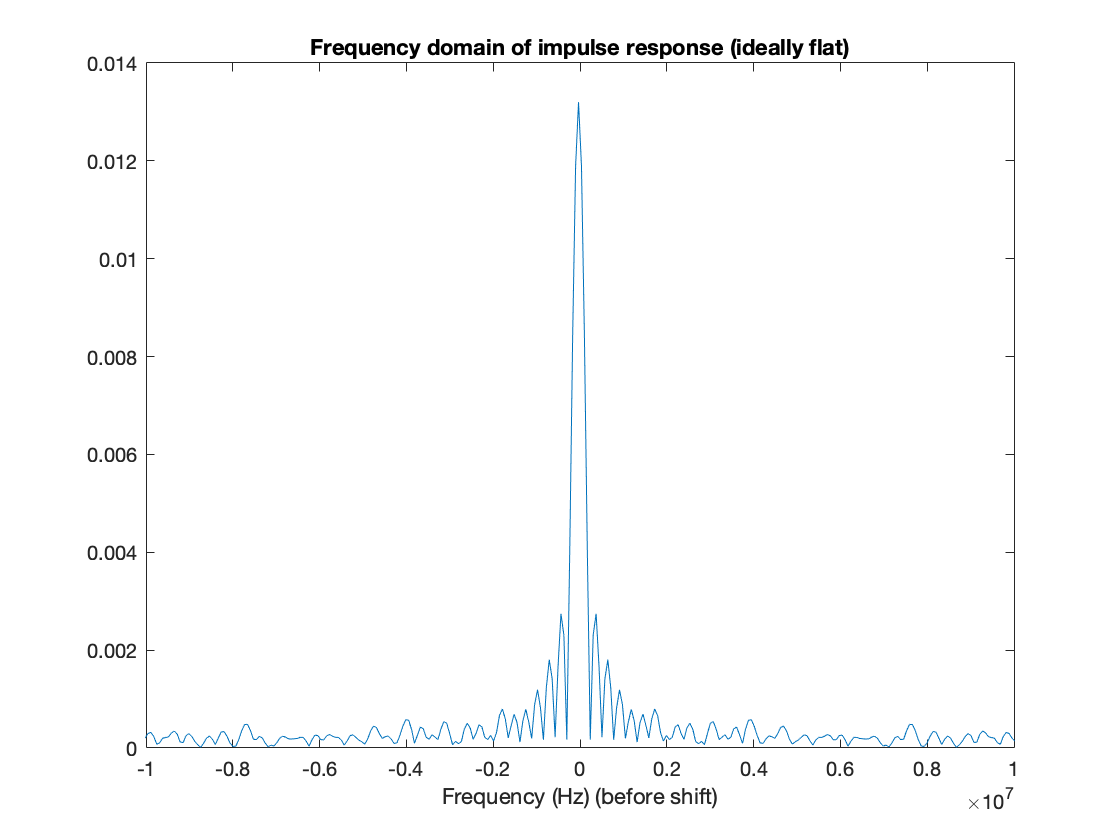

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('Fourier transform before shift')
xlim([-10E6, 10E6]); xlabel('Frequency (Hz) (before shift)'); 
title('Frequency domain of impulse response (ideally flat)'); 

delaySpread(reflectors, W, C, fc); 


The delay spread is 9.264 us
The coherance bandwidth is 53.974 kHz
The signal is in a Frequency selective fading zone


dopplerSpread(reflectors, Rx, W, fc, C); 


The doppler spread is 8.48528 Hz
The coherance time is 29.46278 ms

The doppler spread is 8.48528 Hz
The coherance time is 29.46278 ms


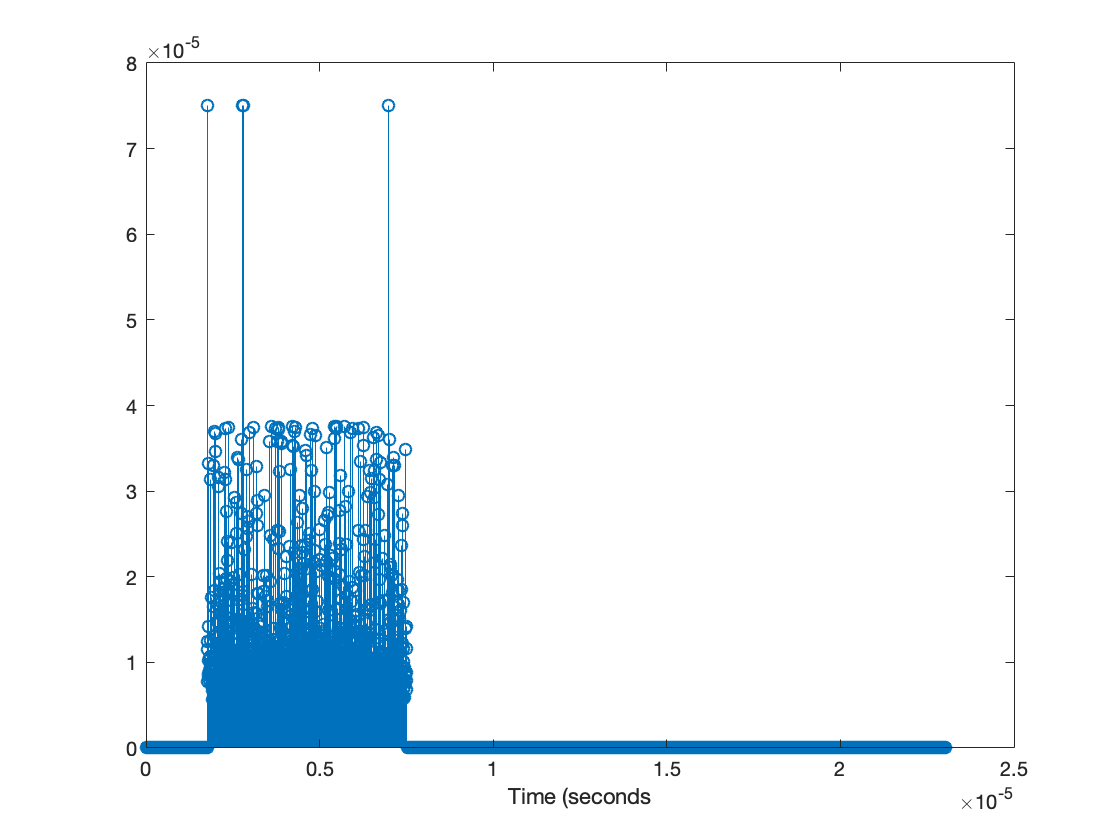


% Take four: r2
clear Rx reflector
Rx.V       = [10,10]; 
Rx.posInit = [500, 1200]; 
reflectors.pos = dreflect2; 
Rx.pos     = recieverPosition(Rx.posInit, Rx.V, 0); 
reflectors.range  = pathLength(Tx.pos, Rx.pos, reflectors.pos);
reflectors.atten  = pathAttenuation(Grx, Gtx, lambdaC, reflectors.range);
reflectors.pDelay = pathDelay(reflectors, C);
[reflectors.h, channelImpt] = channelImpResp(reflectors, reflectors.pDelay, length(reflectors.pDelay)+2000); 
figure; stem(channelImpt, reflectors.h); xlabel('Time (seconds'); 

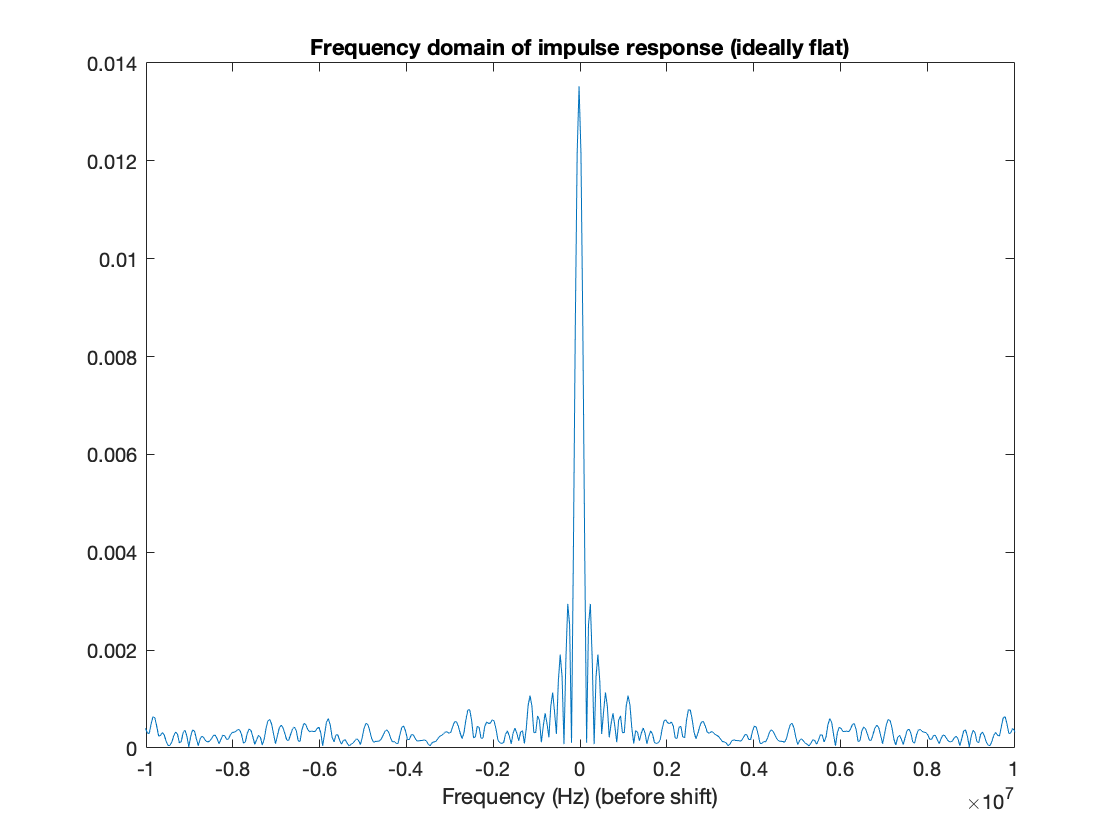

fs = 1/(channelImpt(2)-channelImpt(1)); f = fs*(-length(channelImpt)/2:length(channelImpt)/2)./length(channelImpt); 
Y = fft(reflectors.h); figure; plot(f(1:end-1), abs(fftshift(Y))); title('Fourier transform before shift')
xlim([-10E6, 10E6]); xlabel('Frequency (Hz) (before shift)'); title('Frequency domain of impulse response (ideally flat)'); 

delaySpread(reflectors, W, C, fc); dopplerSpread(reflectors, Rx, W, fc, C); 


The delay spread is 13.978 us
The coherance bandwidth is 35.771 kHz
The signal is in a Frequency selective fading zone

The doppler spread is 84.84931 Hz
The coherance time is 2.94640 ms

The doppler spread is 84.84931 Hz
The coherance time is 2.94640 ms



%% (i): Values are printed in the above function calls


## (j): Coherance BW is a good approximation of the frequency range 

At the very least, it appears to be orders of magnitude accurate. I do not see any indication it is a direct 3dB calculations, but the wider frequency contents have a reasonable value, as do the narrow bands. 

## (k): Coherance time indicates how long the channel is stable

Use either time or frequency impulse data to describe how long the channel is stable... not sure how to do this. 

## (l): Flat / dynamic fading

The scenarios with more echos undergo frequency selective fading. Essentially these are longer boxes <--> narrower boxes in frequency. Yes, it agrees with the frequency results. I am probably missing something important... 

## (m): Delay requirement is one second, how does that affect fade-speed

That sounds like a very large (relatively) delay requirement. Thus most channels will remain fast-fading relatively. Howver, the first trial (less reflections and less doppler) has a very long coherance time. This indicates it will be a slow fading channel in this setup. 

function range = pathLength(Tx, Rx, reflectors)
    % Assumes fixed transmitter and reciever
    % Fixed, but multiple reflectors
    % Calculates round-trip trip
    if ~isequal(reflectors(1,:), Tx) || ~isequal(reflectors(1,:), Rx) % Calculate the direct path; 
        reflectors = [0, 0; reflectors]; 
    end
    range = zeros(1, length(reflectors)); 
    
    for i = 1:length(reflectors)
        temp1    = sqrt((Tx(1) - reflectors(i, 1)).^2 + (Tx(2) - reflectors(i, 2)).^2);
        temp2    = sqrt((Rx(1) - reflectors(i, 1)).^2 + (Rx(2) - reflectors(i, 2)).^2);
        range(i) = temp1 + temp2;
    end
end

function Rx = recieverPosition(RxInitial, V, t) 
    % Takes initial reciever position and estimates new position
    % Assumes V is time-invariant
    % Assumes t is an array of times
    
    Rx = zeros(size(V) + [1, 0]);
    
    Rx(1,:) = RxInitial; 
    for i = 1:length(t)
        Rx(i+1, :) = RxInitial + V.*t(i); 
    end
end

function pathAtten   = pathAttenuation(Grx, Gtx, lambdaC, pathLength)
    % Strictly speaking, I would not consider Tx/Rx gains
    % attenuation
    % Pathlength is allowed to change with time
    % All other variables should be time invariant, scalars
    pathAtten = ( sqrt(Gtx*Grx)*lambdaC/(4*pi) ) ./ (pathLength); 
end

function pDelay = pathDelay(rx, C) % Global variables suck
    pLength = rx.range; 
    % Returns delay time in seconds
    pDelay      = pLength ./ (C) ; 
end

function [channelImp channelImpt] = channelImpResp(rx, t, N)
    % Expects rx to be a struct with precalculated delays
    % Time is arbitrary
    
    % Equation 2.18
    pDelay      = rx.pDelay; 
    atten       = rx.atten;
    h           = zeros(1,length(t)); 
    for ii= 1:length(t)
        temp  = sum(atten(round(pDelay,10) ==  round(t(ii),10)));
        h(ii) = temp;
    end
    channelImp = resample(h, linspace(pDelay(1), pDelay(end), length(h))); % Might want to make this not start at zero
    dt = (length(channelImp)/(pDelay(end) - pDelay(1)))^(-1); 
    Nz = zeros(1, N); 
    channelImp = [0.*(0:dt:(pDelay(1)-dt)), channelImp, 0.*((pDelay - dt):dt:N*dt)]; 
    channelImpt = linspace(0, N*dt, length(channelImp)); 
            % Necessary for basic fourier theory and abstracting to
            % function of time...? 
    
end

function h = dtbIR(recieverStruct)
    W = 1E7; fc = 1E8; % I
    M = 0:200; l = linspace(-4*pi, 4*pi); 

    h = zeros(1, length(l)); 
    for it = 1:length(recieverStruct.atten)
        ai  = recieverStruct.atten(it); 
        Ti  = recieverStruct.pDelay(it);
        aib = ai.*exp(-sqrt(-1).*2*pi*fc*Ti); 
        
            toBeSummed = aib.*sinc(l - Ti.*W); 
            h = h + toBeSummed; % yyaxis right; plot(abs(h)); 

            if length(recieverStruct.atten) < 20
                yyaxis left; hold on; plot(abs(toBeSummed));  
                yyaxis right; hold off; plot(abs(h)); pause(0.1)
            end
        % plot(abs(toBeSummed)); drawnow; pause(0.1); 
    end
    title('Effect of each scatterer'); ylabel('Sum'); 
    yyaxis left; ylabel('Individual'); 
    figure;
end
function rSt = delaySpread(rSt, W, C, fc)
   % W = 1E7; fc = 1E8; % I should not have to do this... 
    pDelays = rSt.pDelay;
    rSt.Td = range(pDelays); 
    rSt.Wc = 1/2/rSt.Td; 
    if      rSt.Wc > W/10; rSt.fading = 'flat';
    elseif  rSt.Wc < 10*W; rSt.fading = 'Frequency selective';
    else;                  rSt.fading = 'inbetween'; end
    fprintf('\nThe delay spread is %01.3f us\nThe coherance bandwidth is %01.3f kHz\n', ...
             rSt.Td.*1E6, rSt.Wc.*1E-3)
    disp(['The signal is in a ', rSt.fading, ' fading zone'])
end
function rSt = dopplerSpread(rSt, Rx, W, fc, C)
    % This seems like its much more complex than my assumptions...
    % Stationary transmitter and reciever really simplify this....
    
    % Bistatic sorta situation
    %   range-rate Tx-Ref --> 0; 
    %   Only need Ref-rec. Roving reciever
    %W = 1E7; fc = 1E9; C = 3E8; 
    refPos = rSt.pos;
    for i = 1:length(Rx.pos) % Time iterater
        recPosX = Rx.pos(i, 1); recPosY = Rx.pos(i, 2);
        vecIn  = [recPosX- refPos(:, 1), recPosY - refPos(:, 2)]; 
        % Assume only the direct path from the reflector matters
        % I may be totally wrong with this algebra
        for ii = 1:length(vecIn)
            vecIn(ii, :)  = vecIn(ii,:)./norm(vecIn(ii,:));
            rangeR(ii,:)  = dot(vecIn(ii,:), Rx.V);
        end
        delayRate    = rangeR/C; 
        rSt.di(i, :) = fc.*      delayRate; 
        rSt.Ds(i)    = fc *range(delayRate); 
        rSt.Tc(i)   = 1/4/rSt.Ds(i);
        fprintf(['\nThe doppler spread is %01.5f Hz\nThe coherance time is %01.5f ms\n'],rSt.Ds(i), rSt.Tc(i).*1E3)
    end
    


end
    

    
    
    
    
